# Using ADI Transceiver Toolbox System Objects

We now look at how the Transceiver Toolbox system objects can be configured and used to stream data to and from the radio. Let us start with an example that uses ADALM-Pluto to stream data.

## adi.Pluto.Tx and adi.Pluto.Rx

Let us begin by instantiating the Pluto Tx system object. 

clear all;
plutoTx = adi.Pluto.Tx

plutoTx =   adi.Pluto.Tx with properties:

        CenterFrequency: 2.4000e+09
           SamplingRate: 3000000
            RFBandwidth: 3000000
    AttenuationChannel0: -30
           RFPortSelect: 'A'
     EnableCustomFilter: false
                    uri: 'ip:10.0.0.200'
        EnabledChannels: 1
             DataSource: 'DMA'
    EnableCyclicBuffers: false


Some of the properties of the plutoTx system object will seem straightforward. **AttenuationChannel0** applies the desired level of attenuation to the signal before it gets transmitted. **DataSource** is specified as either 'DMA', which specifies the MATLAB as the source of the data, or 'DDS', which specifies the DDS on the radio hardware as the source of the data. Let us first update the URI to the default IP address and select the DDS as the data source. The last statement in the code fragment below calls the transmitter system object and transmits the DDS waveform continuously. 

plutoTx.uri = 'ip:192.168.3.1';
plutoTx.AttenuationChannel0 = -15;
plutoTx.DataSource = 'DDS';
plutoTx.DDSFrequencies = repmat(1e5, 2, 2);
plutoTx.DDSScales = [1 1; 0 0];
plutoTx.DDSPhases(1, 1) = 90e3;
plutoTx.DDSPhases(2, 1) = 90e3;
plutoTx();

## Buffer Captures and Discontinuities

Now, let us instantiate the Pluto Rx system object, update the URI and configure the receiver AGC in slow attack mode. 

plutoRx = adi.Pluto.Rx('uri','ip:192.168.3.1','GainControlModeChannel0','slow_attack')

plutoRx =   adi.Pluto.Rx with properties:

             CenterFrequency: 2.4000e+09
                SamplingRate: 3000000
                 RFBandwidth: 3000000
     GainControlModeChannel0: 'slow_attack'
                LoopbackMode: 0
    EnableQuadratureTracking: true
          EnableRFDCTracking: true
    EnableBasebandDCTracking: true
                RFPortSelect: 'A_BALANCED'
             SamplesPerFrame: 32768
          EnableCustomFilter: false
                         uri: 'ip:192.168.3.1'
             EnabledChannels: 1


Additionally, let us set the number of kernel buffers to 1 and grab a frame. 

plutoRx.kernelBuffersCount = 1; 
% plutoRx.LoopbackMode = 1;
pause(1);
y = plutoRx();

You will notice that *y* is a 32768 element complex double column vector passed to MATLAB from iiod running on ADALM-Pluto. 

***NOTE*** - In the code fragment shown above, setting the **LoopbackMode** property to 1 enables digital loopback mode and bypasses the RF hardware, a useful feature for debugging purposes. Alternatively, in order to observe a relatively clean waveform, it is recommended that the Tx and Rx ports of your Pluto device are connected by a cable. Be sure that the **AttenuationChannel0** property of plutoTx object doesn't exceed -10 in order to protect the RF front end. 

Let us now plot the data

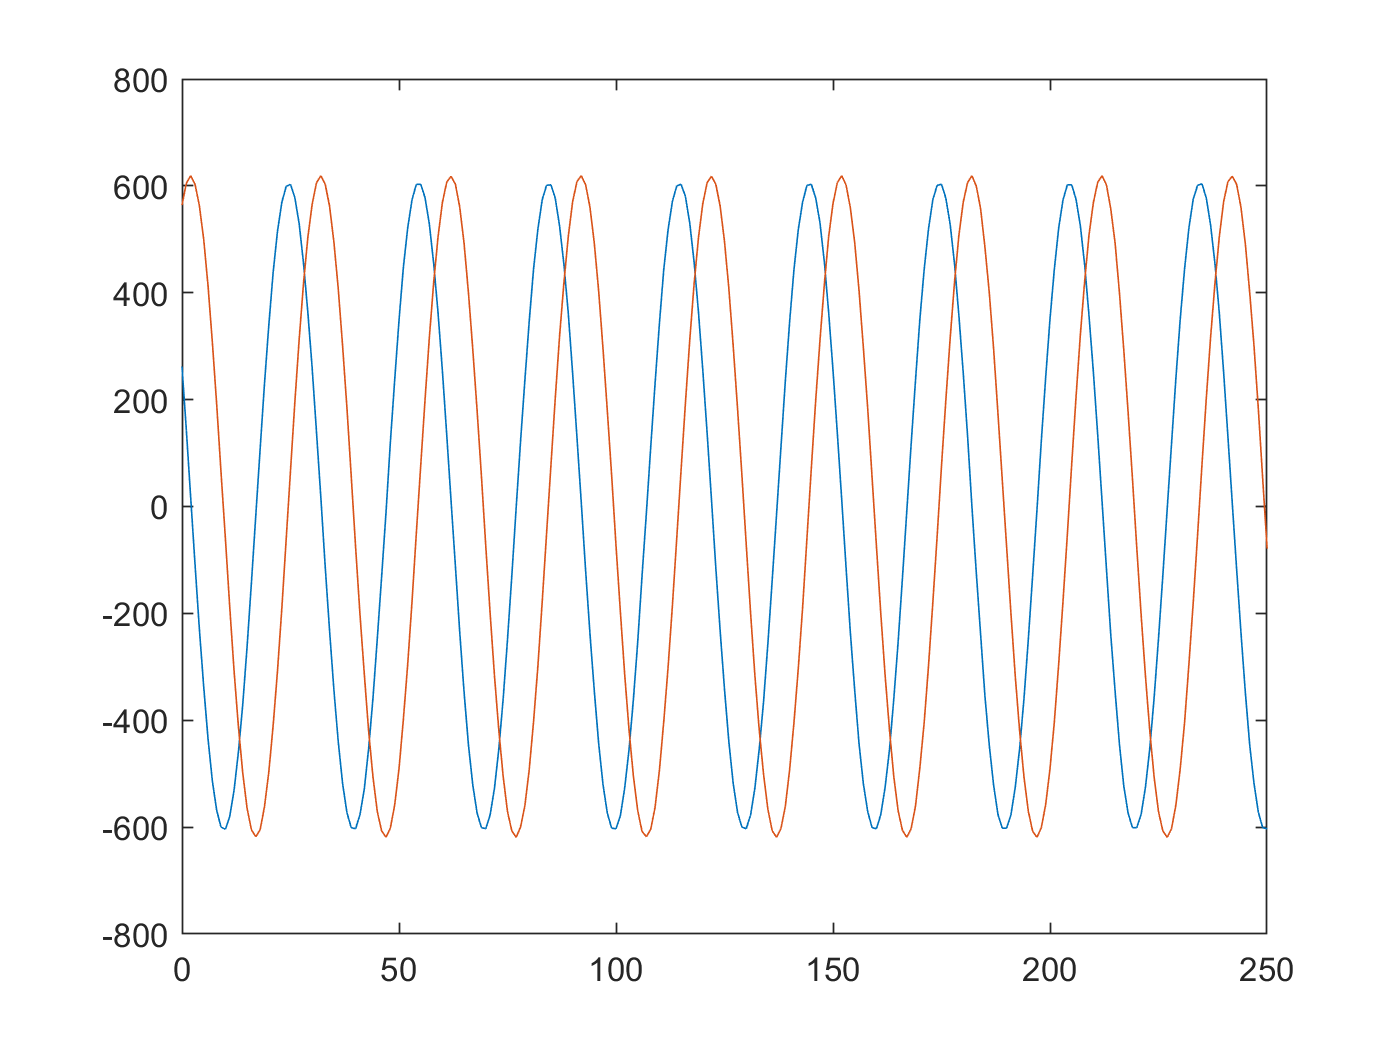

figure; plot(0:2^15-1, real(y), 0:2^15-1, imag(y)); xlim([0 250]);

While most of the properties in the **plutoRx** system object might seem straightforward, the properties **kernelBuffersCount** and **SamplesPerFrame** need some explanation. When the **plutoRx** operator is called for the first time, the kernel buffers are created within the DMA on Pluto itself. Their default number is four, are arranged as a circular buffer and they begin to be filled when the operator is called. Once the first buffer is full, it is returned and the remaining ones will continue to fill. As soon as one is requested, it frees up space for the next one. Therefore, the first four buffers are guaranteed to be contiguous. If buffers are not requested/pulled fast enough, data can be dropped between buffers after the first four. The maximum number of samples that can be captured with each buffer is 2^20. A general rule is to set the buffer size large if the sample rate is higher. in order to keep up with the device.

Let us now see a demonstration of this discontiguous nature of samples between buffer pulls.

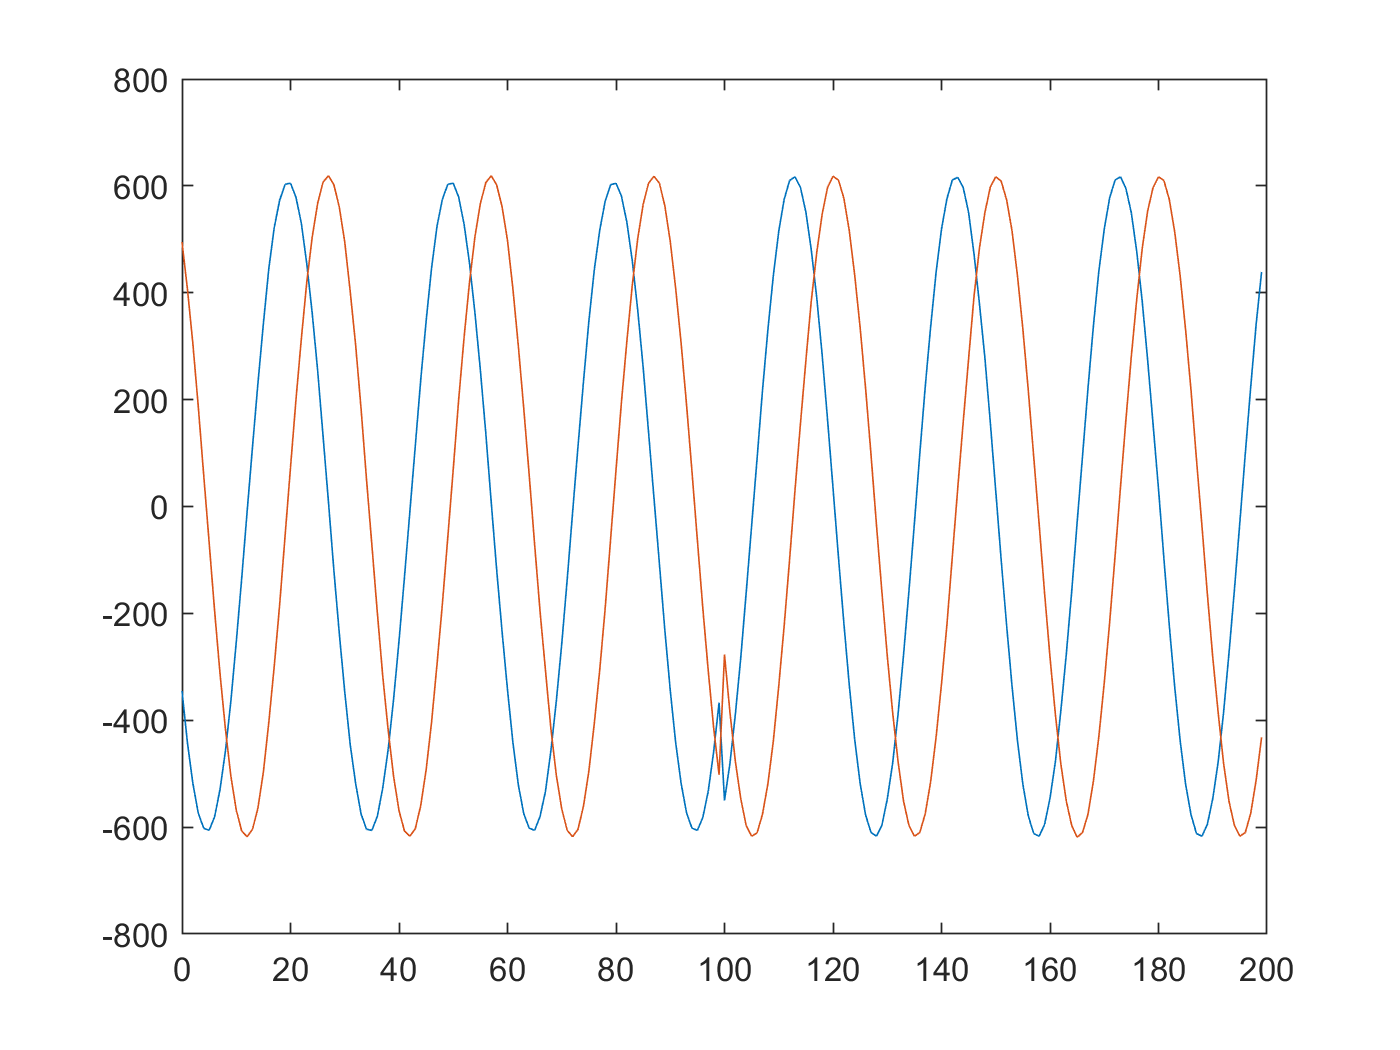

pause(5);
z = plutoRx();
figure; plot(0:199, real([y(end-99:end); z(1:100)]), 0:199, imag([y(end-99:end); z(1:100)]));

As you can see from the previous code fragment, there is a disconuity between the last 100 samples of a buffer capture and the first 100 samples of the subsequent buffer capture. However, note that the *subsequent* buffer capture does not contain the next temporally continuous set of samples. This is due to the delay that any signal processing performed between buffer captures might introduce as represented by the **pause(5)** command which will cause those in-between samples to be dropped by the radio. Hence, 

It is possible that when you run this experiment on your machine, you will not be able to observe a complex sinusoid in the previous two figures. This is because, any interaction with the radio is bound to be asynchronous since the communication is over USB. Depending on contention, the OS etc., the calls to the transmit and receive system objects need not occur in the order they appear in a MATLAB script. One way to reduce this possibility is to increase the time between transmit and receive calls. The **pause(1)** command prior to calling the **plutoRx** operator is intended to serve this purpose. Another way is to keep polling the buffers until the first valid buffer is received. 

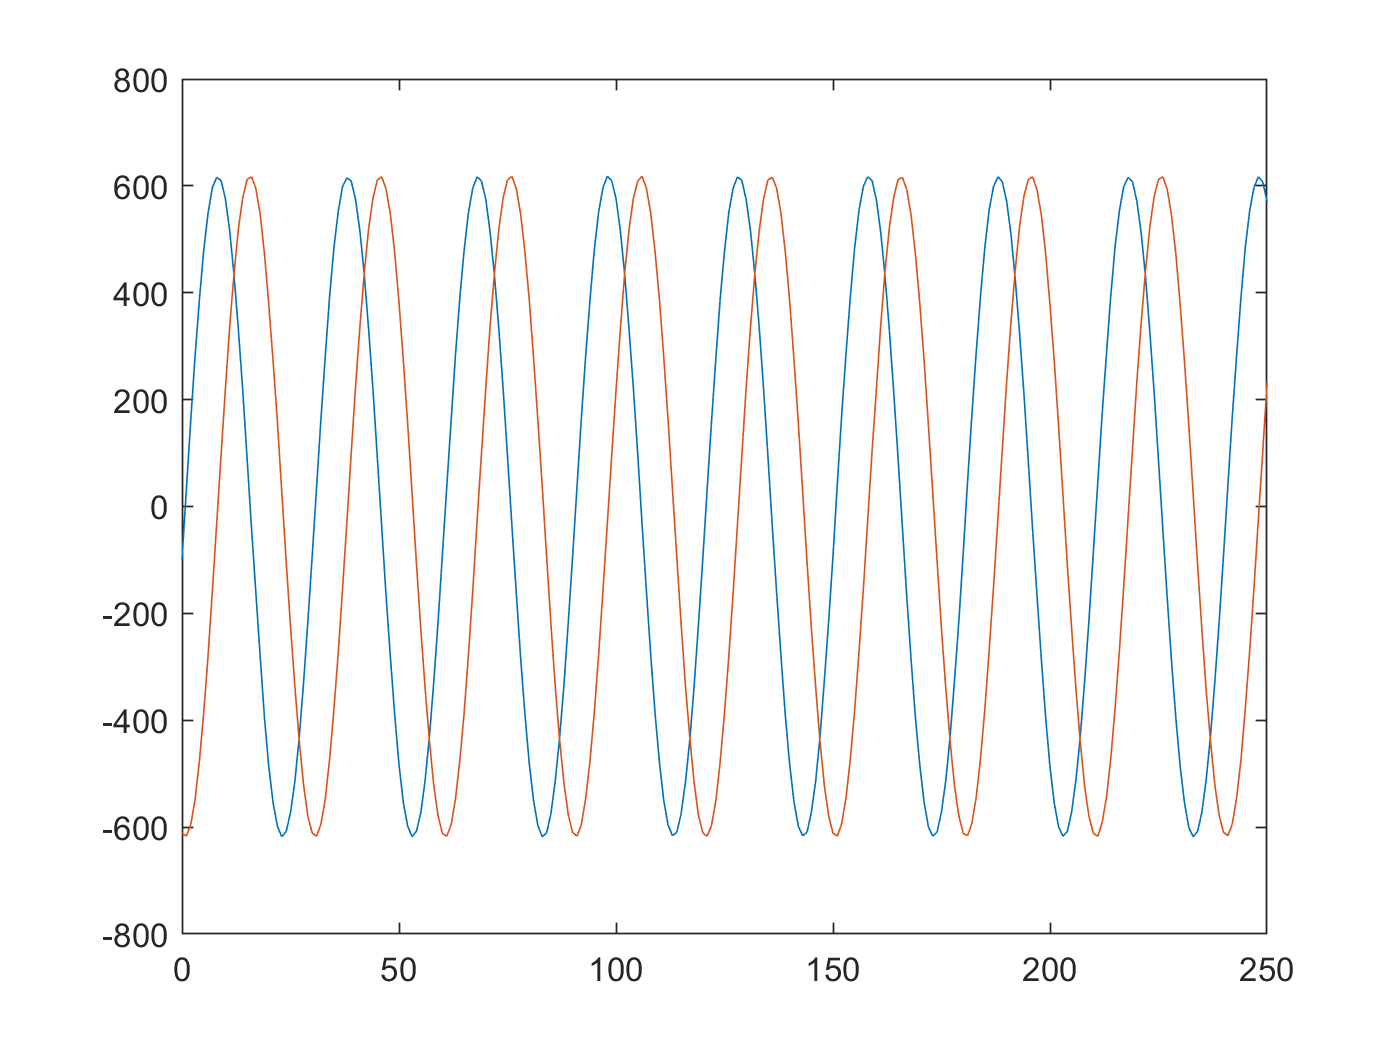

for n = 1:20
    valid = false;
    while ~valid
        [y, valid] = plutoRx();
    end
end
figure; plot(0:2^15-1, real(y), 0:2^15-1, imag(y)); xlim([0 250]);

release(plutoTx);
release(plutoRx);

Finally, the release methods destroys all buffers and you reconnect to the device and redesign the programmable filters when the operators for the system objects are called next time.